**For each of the following parameters, they may either be set using the sliders, or, simulated over a range of values by clicking the range button. **

### **Battery Parameters:**

Capacity:

Ah_V = 2.2; Ah_S = false;if Ah_S  Ah_R = [0 31.7];
    disp("Capacity set to range: " + Ah_R(1) + " -> " + Ah_R(2) + "Amp-Hours");
else 
    disp("Capacity set to value:"+ m_V + "Amp-Hours");
end

Capacity set to value:5Amp-Hours


Nominal Voltage:

V_V = 0.3; V_S = false;if V_S  V_R = [14.4 31.7];
    disp("Nominal Battery Voltage set to range: " + V_R(1) + " -> " + V_R(2)+" Volts");
else 
    disp("Nominal Battery Voltage set to value:"+ V_V + " Volts");
end

Nominal Battery Voltage set to value:0.3 Volts


Efficiency factor:

E = 2;

- 
$$\text{Battery Capacity (Wh)} = \text{Capacity (Ah)} \times \text{Nominal Voltage (V)}$$


if ~V_S && ~Ah_S
    Wh_V = Ah_V*V_V;
    disp("Battery Capacity = "+ Wh_V + " Watt Hours" )
end

Battery Capacity = 0.66 Watt Hours


### Vehicle Parameters:

m_V = 5; m_S = true;if m_S  m_R = [0 15.1];
    disp("Mass set to range: " + m_R(1) + " -> "  + m_R(2) + "kg");
else 
    disp("Mass set to value:"+ m_V + "kg");
end

Mass set to range: 0 -> 15.1kg


### Propeller Parameters:

k_m_V = 0.01442; k_m_S = false; if k_m_S k_m_R = [25 100];
    disp("k_m set to range: " + k_m_R(1)+ " -> " + k_m_R(2));
else 
    disp("k_m set to value:"+ k_m_V);
end

k_m set to value:0.01442


k_f_V = 0.818845; k_f_S = false; if k_f_S k_f_R = [25 72.7];
    disp("k_f set to range: " + k_f_R(1)+ " -> " + k_f_R(2));
else 
    disp("k_f set to value:"+ k_f_V);
end

k_f set to value:0.81885


### Motor Parameters:

KV_V = 20; KV_S = false; if KV_S    KV_R = [19 100];
    disp("KV set to range: " + KV_R(1) + " -> " + KV_R(2) + " (Rpm/V)");
else 
    disp("KV set to value:"+ KV_V + " (Rpm/V)");
end

KV set to value:20 (Rpm/V)


I_o_V = 20; I_o_S = false; if I_o_S     I_o_R = [41.3 100];
    disp("I_o set to range: " + I_o_R(1)+" -> " + I_o_R(2) + " (A)");
else 
    disp("I_o set to value:"+ I_o_V + " (A)");
end

I_o set to value:20 (A)


R_m_V = 30; R_m_S  = false; if R_m_S == true     R_m_R = [9.5 100];
    disp("R_m set to range: " + R_m_R(1) + " -> " + R_m_R(2) +" (Ohms)" );
else 
    disp("R_m set to value:"+ R_m_V + " (Ohms)");
end

R_m set to value:30 (Ohms)



$$
    P_e= R_m\left(\frac{ k_mmg KV^*2\pi}{604k_f}+I_o\right)^2 + k_m\sqrt{\frac{mg}{4k_f}}^3+\frac{60I_o\sqrt{\frac{mg}{4k_f}}}{2\pi(KV^*)}$$



$$\text{Usable Runtime (hours)} = \frac{\text{Battery Capacity (Wh)}}{\text{Power Draw (Watts)}} \times \text{Efficiency Factor}$$


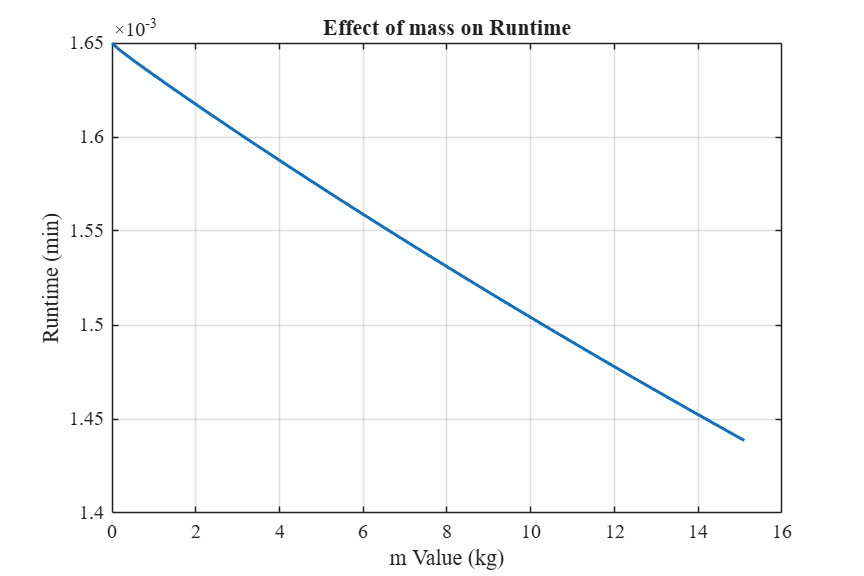

if k_m_S
    km_range = linspace(k_m_R(1),k_m_R(2),100);
    P_e = calculatePe(km_range,k_f_V,m_V,KV_V,I_o_V,R_m_V);
    runtime_minutes = (Wh_V./(4.*P_e)).*E.*60;
    % Plot
    figure('Units', 'inches', 'Position', [1, 1, 6, 4]); % Standard report figure size
    plot(km_range, runtime_minutes, 'LineWidth', 1.5);
    grid on;

    % Labels (Always include units!)
    xlabel('k_m Value');
    ylabel('Runtime (min)');
    title('Effect of k_m on Runtime');

    % Report Formatting Tweaks
    set(gca, 'FontName', 'Times New Roman', 'FontSize', 10, 'Box', 'on');

    % Export high-res vector PDF for report
    exportgraphics(gcf, 'figure.pdf', 'ContentType', 'vector');

end
if k_f_S
    kf_range = linspace(k_f_R(1),k_f_R(2),100);
    P_e = calculatePe(k_m_V,kf_range,m_V,KV_V,I_o_V,R_m_V);
    runtime_minutes = (Wh_V./(4.*P_e)).*E.*60;
    % Plot
    figure('Units', 'inches', 'Position', [1, 1, 6, 4]); % Standard report figure size
    plot(kf_range, runtime_minutes, 'LineWidth', 1.5);
    grid on;

    % Labels (Always include units!)
    xlabel('k_f Value');
    ylabel('Runtime (min)');
    title('Effect of k_f on Runtime');

    % Report Formatting Tweaks
    set(gca, 'FontName', 'Times New Roman', 'FontSize', 10, 'Box', 'on');

    % Export high-res vector PDF for report
    exportgraphics(gcf, 'figure.pdf', 'ContentType', 'vector');
end
if m_S
    m_range = linspace(m_R(1),m_R(2),100);
    P_e = calculatePe(k_m_V,k_f_V,m_range,KV_V,I_o_V,R_m_V);
    runtime_minutes = (Wh_V./(4.*P_e)).*E.*60;
    % Plot
    figure('Units', 'inches', 'Position', [1, 1, 6, 4]); % Standard report figure size
    plot(m_range, runtime_minutes, 'LineWidth', 1.5);
    grid on;

    % Labels (Always include units!)
    xlabel('m Value (kg)');
    ylabel('Runtime (min)');
    title('Effect of mass on Runtime');

    % Report Formatting Tweaks
    set(gca, 'FontName', 'Times New Roman', 'FontSize', 10, 'Box', 'on');

    % Export high-res vector PDF for report
    exportgraphics(gcf, 'figure.pdf', 'ContentType', 'vector');
end

if KV_S
    KV_range = linspace(KV_R(1),KV_R(2),100);
    P_e = calculatePe(k_m_V,k_f_V,m_V,KV_range,I_o_V,R_m_V);
    plot(KV_range,P_e);
    runtime_minutes = (Wh_V./(4.*P_e)).*E.*60;
    % Plot
    figure('Units', 'inches', 'Position', [1, 1, 6, 4]); % Standard report figure size
    plot(KV_range, runtime_minutes, 'LineWidth', 1.5);
    grid on;

    % Labels (Always include units!)
    xlabel('KV Value (rpm/V)');
    ylabel('Runtime (min)');
    title('Effect of KV on Runtime');

    % Report Formatting Tweaks
    set(gca, 'FontName', 'Times New Roman', 'FontSize', 10, 'Box', 'on');

    % Export high-res vector PDF for report
    exportgraphics(gcf, 'figure.pdf', 'ContentType', 'vector');
end
if I_o_S
    I_o_range = linspace(I_o_R(1),I_o_R(2),100);
    P_e = calculatePe(k_m_V,k_f_V,m_V,KV_V,I_o_range,R_m_V);
    runtime_minutes = (Wh_V./(4.*P_e)).*E.*60;
    % Plot
    figure('Units', 'inches', 'Position', [1, 1, 6, 4]); % Standard report figure size
    plot(I_o_range, runtime_minutes, 'LineWidth', 1.5);
    grid on;

    % Labels (Always include units!)
    xlabel('$I_o$ Value (Amps)');
    ylabel('Runtime (min)');
    title('Effect of $I_o$ on Runtime');

    % Report Formatting Tweaks
    set(gca, 'FontName', 'Times New Roman', 'FontSize', 10, 'Box', 'on');

    % Export high-res vector PDF for report
    exportgraphics(gcf, 'figure.pdf', 'ContentType', 'vector');
end
if R_m_S
    R_m_range = linspace(R_m_R(1),R_m_R(2),100);
    P_e = calculatePe(k_m_V,k_f_V,m_V,KV_V,I_o_range,R_m_range);
    runtime_minutes = (Wh_V./(4.*P_e)).*E.*60;
    % Plot
    figure('Units', 'inches', 'Position', [1, 1, 6, 4]); % Standard report figure size
    plot(R_m_range, runtime_minutes, 'LineWidth', 1.5);
    grid on;

    % Labels (Always include units!)
    xlabel('R_m Value (Ohms)');
    ylabel('Runtime (min)');
    title('Effect of R_m on Runtime');

    % Report Formatting Tweaks
    set(gca, 'FontName', 'Times New Roman', 'FontSize', 10, 'Box', 'on');

    % Export high-res vector PDF for report
    exportgraphics(gcf, 'figure.pdf', 'ContentType', 'vector');
end



# If Working With Data From Excel Sheet:


dataTable = readtable('Parramers.xlsx');

% Extract specific columns by header name     
BatteryOptions = dataTable.Ah;
AhS = dataTable.Ah;   
VS = dataTable.NominalVoltage;
ES = dataTable.E;
k_mS = dataTable.k_m;
k_fS = dataTable.k_f;
KVS = dataTable.KV;
R_mS = dataTable.R_m;
I_oS = dataTable.I_o;
mass = 2;

Thrust Range is in g's of sustained thrust, (0 being free fall, 1 being hover, 2 being 9.81 m/s^2 upwards)

thrustRange = [0 5];
additionalPower = sum(dataTable.AdditionalPowerDrawsW);

### Select Your Chosen Configuration From Data Sheet

battery = 1; propeller = 1; motor = 1;

Wh = AhS(battery)*VS(battery);

Index exceeds array bounds.

disp("Battery Capacity = "+ Wh_V + " Watt Hours" )
thrustSpace = (linspace(thrustRange(1),thrustRange(2),100));
m_range = thrustSpace.*mass;
P_e = calculatePe(k_mS(propeller),k_fS(propeller),m_range,KVS(motor),I_oS(motor),R_mS(motor));
runtime_minutes = (Wh./(4.*P_e + additionalPower)).*ES(battery).*60;
% Plot
figure('Units', 'inches', 'Position', [1, 1, 6, 4]); % Standard report figure size
plot(thrustSpace, runtime_minutes, 'LineWidth', 1.5);
grid on;

% Labels (Always include units!)
xlabel('Sustained Thrust (gs)');
ylabel('Runtime (min)');
xline(1);
title('Runtime for different thrusts');

% Report Formatting Tweaks
set(gca, 'FontName', 'Times New Roman', 'FontSize', 10, 'Box', 'on');

% Export high-res vector PDF for report
exportgraphics(gcf, 'figure.pdf', 'ContentType', 'vector');



function P_e = calculatePe(k_m,k_f,m,KV,I_o,R_m)
    g = 9.81; %m/s^2
    
    part1 = R_m.*((k_m.*m.*g.*KV.*2.*pi)./(60.*4.*k_f)+I_o).^2;
    part2 = k_m.*(sqrt((m.*g)./(4.*k_f)).^3);
    part3 = (60.*I_o.*sqrt((m.*g)./(4.*k_f)))./(2.*pi.*KV);
    
    P_e = part1+part2+part3;
end